root = "D:\PranavaStudy\IITB\Projects\ITSP2021\n3URL\data";
erpds = imageDatastore(root,"IncludeSubfolders",true,"LabelSource","foldernames");
[trainingData,validationData,testingData] = splitEachLabel(erpds,0.6,0.2,0.2);

net = lgraph_1

net =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:09:00 |       41.41% |       45.39% |       1.4729 |       1.1573 |          0.0010 |
|       2 |          50 |       00:35:29 |       42.19% |       48.41% |       1.0602 |       1.0543 |          0.0010 |
|       4 |         100 |       01:00:31 |       50.00% |       48.99% |       1.0781 |       1.1028 |          0.0010 |
|       6 |         150 |       01:45:48 |       51.56% |       44.14% |       0.9504 |   

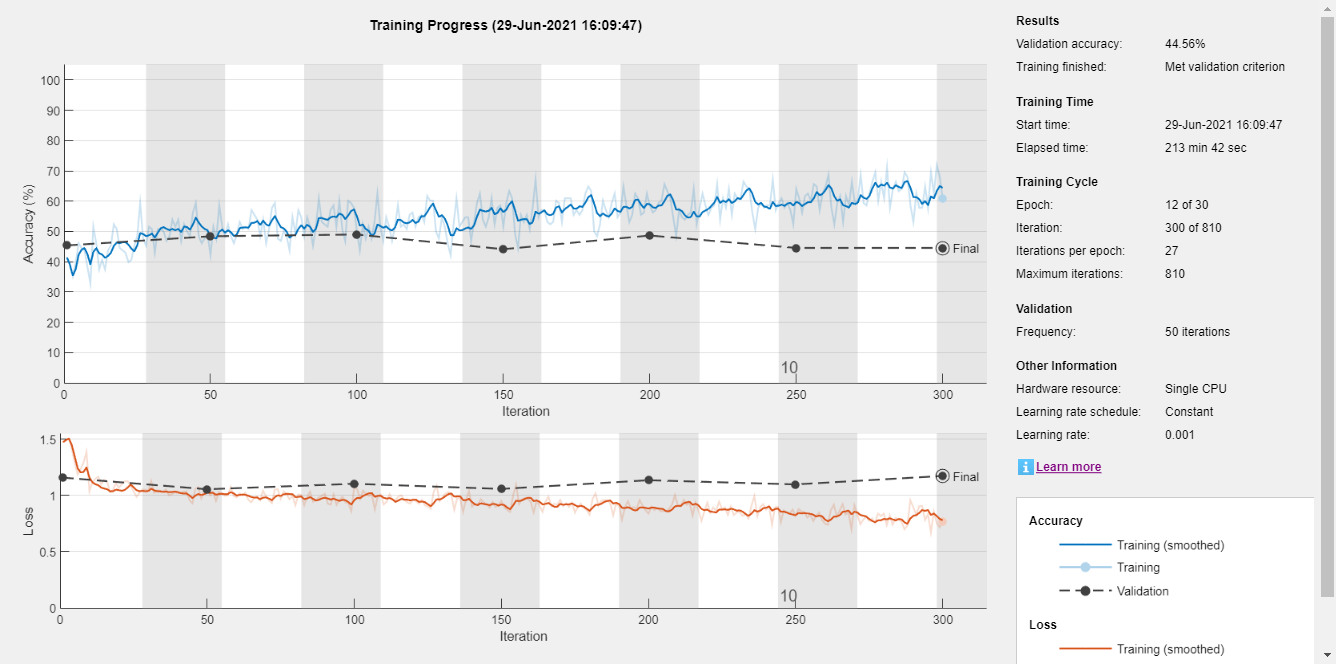

options = trainingOptions("sgdm","InitialLearnRate",0.001,"Plots","training-progress","ValidationData",validationData,"ValidationPatience",5);
[bcinet, info] = trainNetwork(trainingData,net,options);

[testpreds,scores] = classify(bcinet,testingData);
numEqual = nnz(testpreds == testingData.Labels)

numEqual = 445

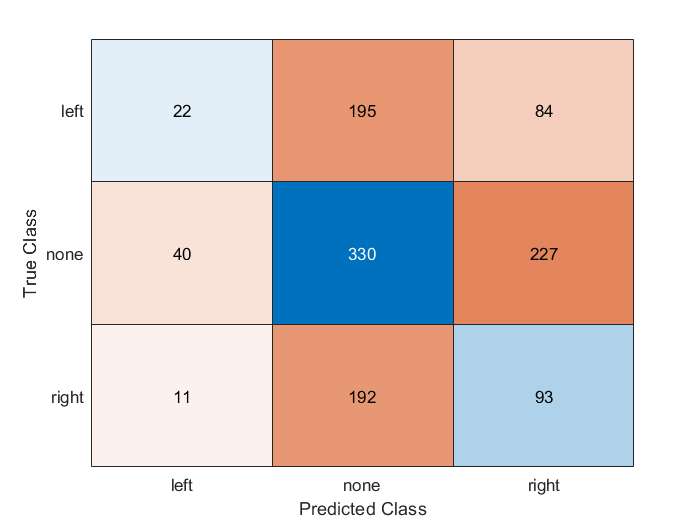

confusionchart(testingData.Labels,testpreds)